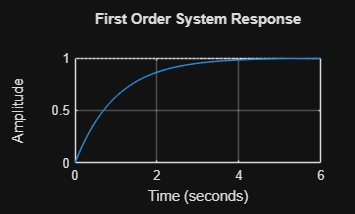

clc
clear
close all

%% FIRST ORDER SYSTEM

K = 1;
tau = 1;

sys1 = tf(K,[tau 1]);

figure
step(sys1)
grid on
title('First Order System Response')


info1 = stepinfo(sys1);
disp('First Order System:')

First Order System:


disp(info1)

         RiseTime: 2.1970
    TransientTime: 3.9121
     SettlingTime: 3.9121
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 7.3222



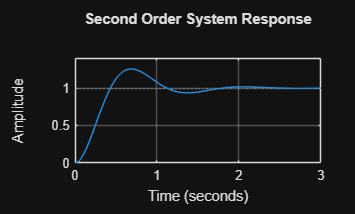



%% SECOND ORDER SYSTEM

wn = 5;
zeta = 0.4;

sys2 = tf(wn^2,[1 2*zeta*wn wn^2]);

figure
step(sys2)
grid on
title('Second Order System Response')


info2 = stepinfo(sys2);
disp('Second Order System:')

Second Order System:


disp(info2)

         RiseTime: 0.2930
    TransientTime: 1.6819
     SettlingTime: 1.6819
      SettlingMin: 0.9065
      SettlingMax: 1.2537
        Overshoot: 25.3741
       Undershoot: 0
             Peak: 1.2537
         PeakTime: 0.6908



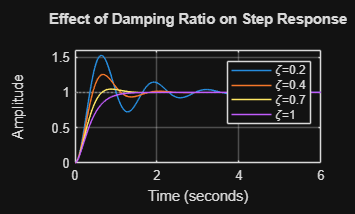



%% EFFECT OF DAMPING RATIO

figure
hold on

zeta_values = [0.2 0.4 0.7 1];

for i=1:length(zeta_values)
    sys = tf(wn^2,[1 2*zeta_values(i)*wn wn^2]);
    step(sys)
end

grid on
legend('\zeta=0.2','\zeta=0.4','\zeta=0.7','\zeta=1')
title('Effect of Damping Ratio on Step Response')